# Sistemi Dinamici - Prova parziale 27/10/2023

**ALBERTO ZURINI **

**voto massimo: 6 punti**

Il voto finale sarà costituito dalla somma delle valutazioni conseguite nei due esercizi.

## Esercizio 1

Due pendoli, rispettivamente di massa $m_1$ ed $m_2$ e con le aste (supposte senza massa) di lunghezza $l_1$ ed $l_2$, sono accoppiati tramite una molla lineare, caratterizzata dalla costante elastica $k$, come in figura

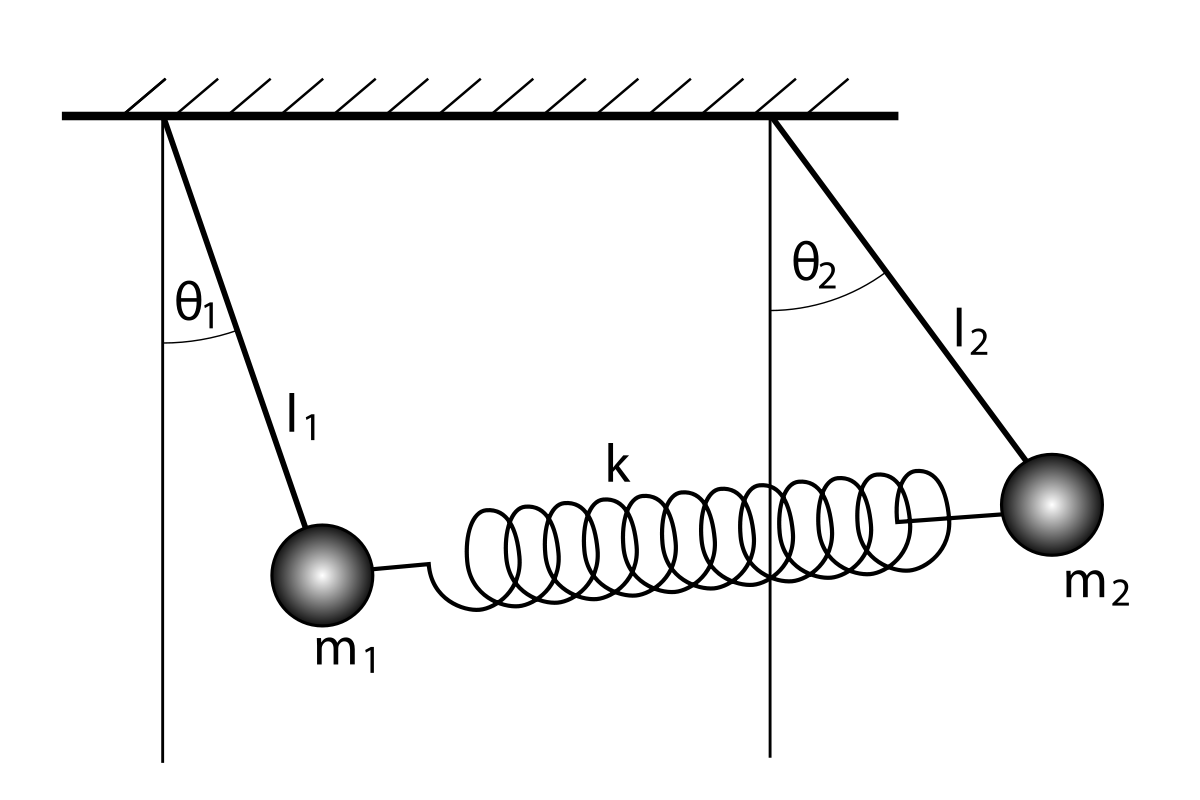

I due pendoli sono sottoposti alla forza di gravità ed alla forza di interazione dovuta alla molla che collega i due pendoli.

Le **variabili di stato** del sistema sono l'inclinazione angolare rispetto alla posizione verticale e la velocità angolare dei due pendoli


$$\begin{array}{lcl}
x_1(t) = \vartheta_1(t) & \quad & x_3(t) = \dot{x}_1(t) = \dot{\vartheta}_1(t) \\
x_2(t) = \vartheta_2(t) & \quad & x_4(t) = \dot{x}_2(t) = \dot{\vartheta}_2(t) 
\end{array}$$


Come **uscite **si assumano le posizioni angolari delle masse dei due pendoli


$$y_1(t) = x_1(t) \qquad y_2(t) = x_2(t)$$


Per semplicità **si assume non ci sia alcun ingresso manipolabile**. L'accelerazione di gravità NON viene considerata un ingresso del sistema, ma semplicemente un parametro delle equazioni di stato.

In definitiva le equazioni di stato del sistema sono le seguenti:


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=& x_3(t) \\
\dot{x_2}(t) &=& x_4(t) \\
\dot{x}_3(t) &=& \displaystyle \frac{1}{m_1\,  l_1} \big[ -\left(m_1 g +k l_1\right) x_1(t) +k l_2 x_2(t) \big] \\
\dot{x}_4(t) &=& \displaystyle \frac{1}{m_2\,  l_2} \big[ -\left(m_2 g +k l_2\right) x_1(t) +k l_1 x_1(t) \big]\\
\\
y_1(t) &=& x_1(t) \\
y_2(t) &=& x_2(t)

\end{array}
\right.$$


Per i parametri si assumano i valori definiti nella tabella

% Inizializzazione:

clear
close all
clc 
% pulizia del workspace di MATLAB prima di iniziare

rng(4321567); % inizializzo il generatore di numeri casuali

### Domanda 1)

 Si chiede di 

- realizzare un modello in equazioni di stato in MATLAB per il sistema a tempo continuo, facendo in modo che le equazioni di stato dipendano dai parametri definiti nella tabella, così che basti semplicemente modificare il valore di uno dei parametri e rieseguire il codice che crea l'oggetto *sistema dinamico* in MATLAB  per ottenere il nuovo modello, senza dover modificare la descrizione del modello stesso.

**Suggerimento**: fare buon uso del comando `ss()`

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

% define the parameters
m1 = 1; %kg
m2 = 10; %kg
l1 = 1; %m
l2 = 1; %m
g = 9.81; %m/s^2
k = 1; % 

% define the matrices for the state-space system
A = [0 0 1 0;
     0 0 0 1
     -1/(m1*l1)*(m1*g + k*l1) 1/(m1*l1)*k*l2 0 0
     1/(m2*l2)*k*l1 -1/(m2*l2)*(m2*g + k*l2) 0 0];
B = [0; 0; 0; 0];
C = [1 0 0 0
     0 1 0 0];
D = [0; 0];

% define the state-space system
sysC = ss(A, B, C, D);

### Domanda 2)

- Utilizzare il sistema dinamico definito nella Risposta 1) per simulare l'evoluzione libera dello stato del sistema per un intervallo di tempo della durata pari a $T=20 \,$s.

- Come condizioni iniziali vanno utilizzate tutte le $4$ combinazioni possibili ottenute combinando in tutti i modi possibili i seguenti  valori

x1_init = 0.1*randn(2,1); % due valori casuali per la componente x_1 dello stato
x2_init = 0.2*randn(2,1); % due valori casuali per la componente x_2 dello stato
x3_init = zeros(2,1); % la componente x_3 dello stato inizializzata sempre a zero
x4_init = zeros(2,1); % la componente x_3 dello stato inizializzata sempre a zero

**Suggerimento**: fare buon uso del comando `initial()`

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

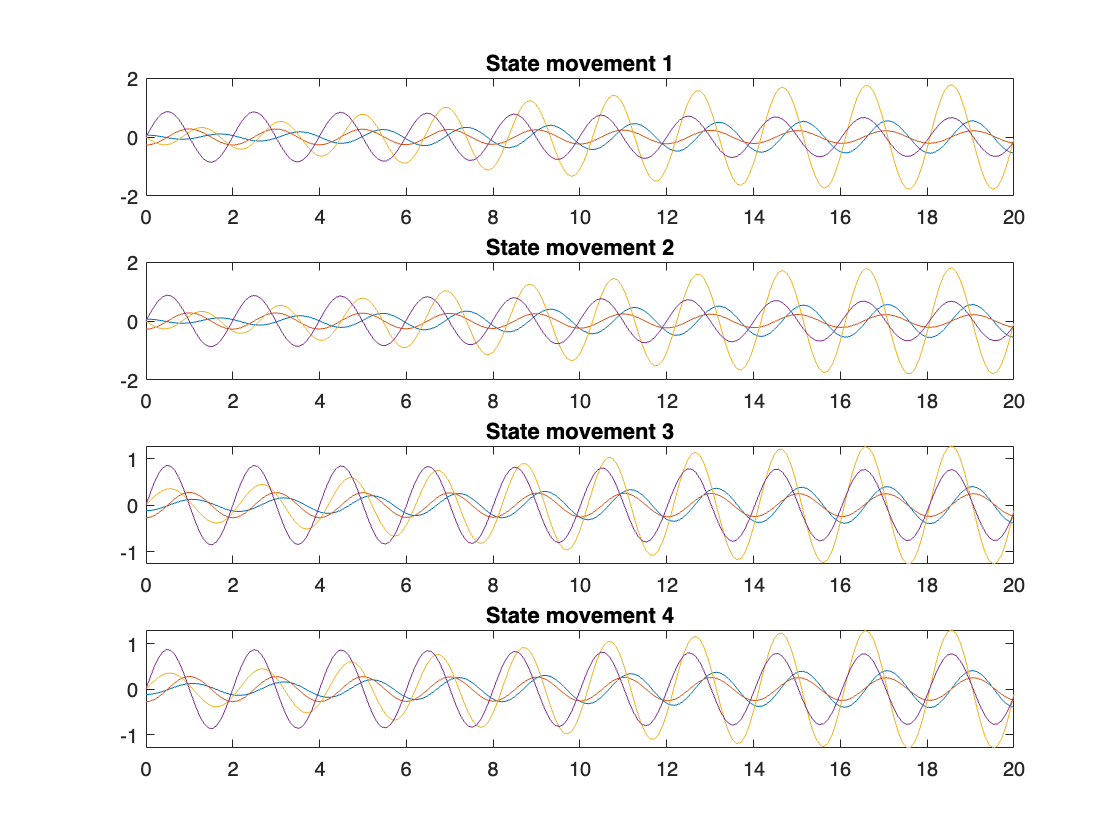

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

% define the simulation time
t_sim = 20; %s

% simulate the system
chart_id = 1;
figure("Name", "Satate movement comparision on different initial states");
for i = 1:2
    for j = 1:2
        [y, tOut, x] = initial(sysC, ...
            [x1_init(i) x2_init(j) x3_init(1) x4_init(1)], ...
            [0 t_sim]); % simulate the system
        
        % plot the state movement:
        subplot(4,1,chart_id);
        plot(tOut, x);
        title("State movement " + chart_id);

        chart_id=chart_id+1;
    end
end

### Domanda 3)

- Raffigurare graficamente e commentare i risultati ottenuti.

**Suggerimento**: fare buon uso del comando `plot()` e del comando `legend().`

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

% done in the previous step

### Domanda 4)

- Sfruttando il modello e le informazioni ottenute nelle risposte alle domande precedenti, determinare un periodo di campionamento $\Delta$ che rispetti il teorema di Shannon.

- Ottenere una descrizione a segnali campionati per il sistema, a partire dal modello a tempo continuo definito in precedenza.

- Simulare l'evoluzione libera dello stato del sistema a segnali campionati, a partire da una delle 4 condizioni iniziali determinate in precedenza e confrontare il risultato con l'evoluzione corrispondente del sistema a tempo continuo.

**Suggerimento**: fare buon uso del comando `c2d()`,  `plot()` e del comando `legend().`

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile


lambdas = eig(A)

lambdas =   -0.0000 + 3.3030i
  -0.0000 - 3.3030i
  -0.0000 + 3.1321i
  -0.0000 - 3.1321i


All the eigenvalues are pure immaginary numbers. This means that we are expecting the state to behave as a periodic function.

Knowing that the general formula for a response mode is $e^{\lambda t}$, where $\lambda$ is an eigenvalue of the system, we can do the following (keeping into account $\lambda = \lambda_R + j \lambda_C$, where in our case $\lambda_R = 0$ and knowing the relationship between complex exponentials and periodic functions). 

Assuming $\lambda_C \in \mathbb{R} \Rightarrow e^{j \lambda_C t} = e^{j 2 \pi f *t} \Rightarrow \lambda_C = 2 \pi f \Rightarrow f = \frac{ \lambda_C}{2 \pi}$

f_m1 = abs( imag(lambdas(1)/(2*pi)) )

f_m1 = 0.5257

f_m3 = abs( imag(lambdas(3)/(2*pi)) )

f_m3 = 0.4985

f_max = max(f_m1, f_m3)

f_max = 0.5257

f_sampling = 40*f_max % Sampling theorem

f_sampling = 21.0277

eig(A)

ans =   -0.0000 + 3.3030i
  -0.0000 - 3.3030i
  -0.0000 + 3.1321i
  -0.0000 - 3.1321i


Ottenere una descrizione a segnali campionati per il sistema, a partire dal modello a tempo continuo definito in precedenza.

Ts = 1/f_sampling;
sysD = c2d(sysC,Ts);

Simulare l'evoluzione libera dello stato del sistema a segnali campionati, a partire da una delle 4 condizioni iniziali determinate in precedenza e confrontare il risultato con l'evoluzione corrispondente del sistema a tempo continuo.

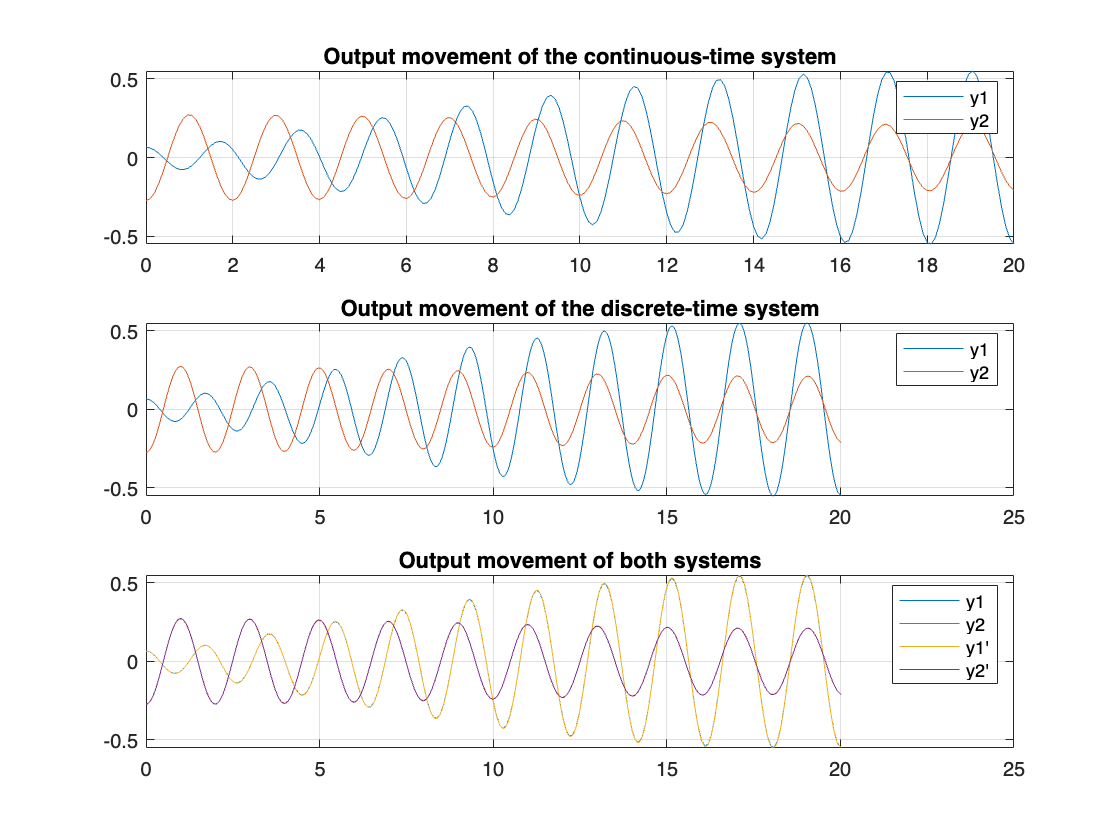

x1_i = 1;
x2_i = 1;

figure("Name", "State movement comparision");
subplot(3,1,1);
[y_c, tOut_c, x_c] = initial(sysC, ...
            [x1_init(x1_i) x2_init(x2_i) x3_init(1) x4_init(1)], ...
            [0 t_sim]); % simulate the system
plot(tOut_c, y_c);
grid on;
title("Output movement of the continuous-time system");
legend("y1", "y2");

subplot(3,1,2);
[y_d, tOut_d, x_d] = initial(sysD, ...
            [x1_init(x1_i) x2_init(x2_i) x3_init(1) x4_init(1)], ...
            t_sim); % simulate the system
plot(tOut_d, y_d);
grid on;
title("Output movement of the discrete-time system");
legend("y1", "y2");

subplot(3,1,3);
plot(tOut_c, y_c);
grid on;
hold on;
plot(tOut_d, y_d);
title("Output movement of both systems");
legend("y1", "y2", "y1'", "y2'");

Having a look at the charts we can be satisfied with the discrete-time approximation of the real system.

### Domanda 5)

- Individuare eventuali pulsazioni di campionamento patologiche.

- Motivare e commentare il risultato ottenuto.

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

A pathological sampling frequency, it's a sampling frequency that is too low to accurately represent the signal, leadingto undesireable effects like aliasing. Such a frequency doesn't satisfy Nyquist criterion.

T_pulse_1 = 1/f_m1;
T_pulse_3 = 1/f_m3;
disp(T_pulse_1 + ", " + T_pulse_3)

1.9022, 2.0061


We can try to sample at a multiple of those pulse frequencies.

k = 2; % the multiple

x1_i = 1;
x2_i = 1;

Tp_1 = T_pulse_1*k

Tp_1 = 3.8045

Tp_2 = T_pulse_3*k

Tp_2 = 4.0121

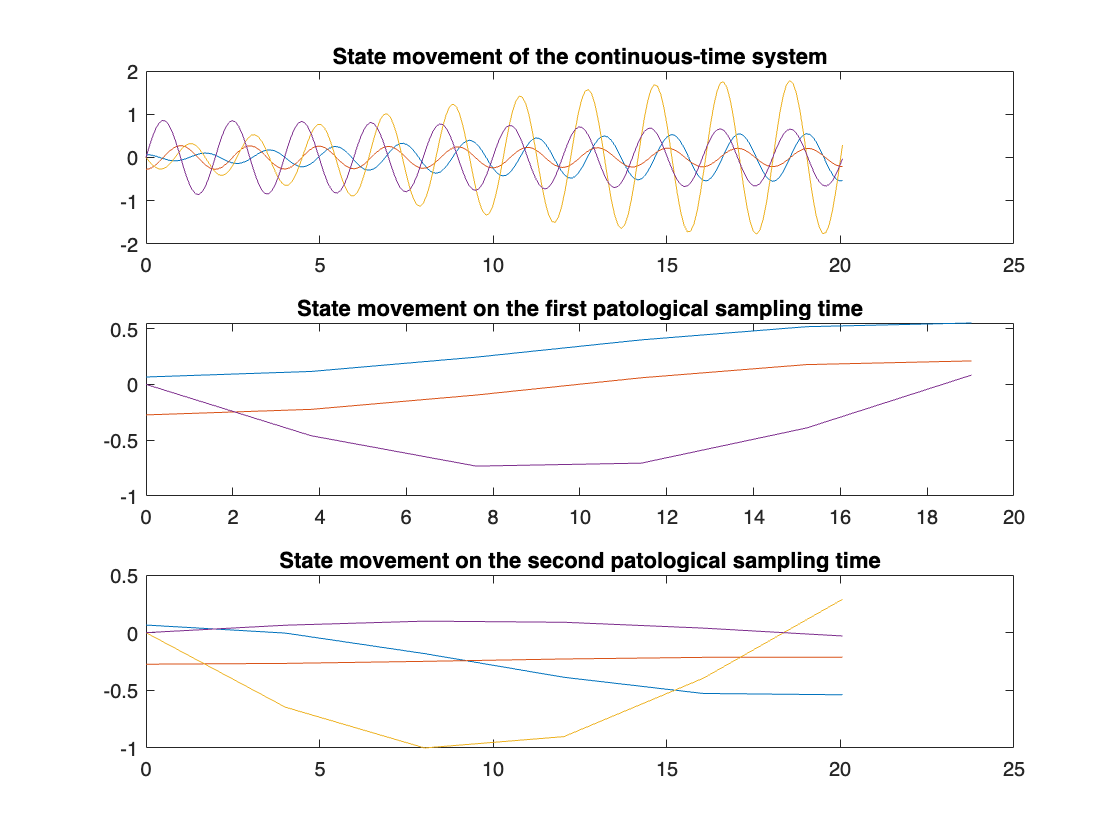


t_sim = 5*max(Tp_1, Tp_2); 
% we want to see the simulation on the long-term to better compare the
% behavior of the system

sysD_P1 = c2d(sysC,Tp_1);
sysD_P2 = c2d(sysC,T_pulse_3*k);

figure("Name", "State movement on the patological sampling times");

subplot(3,1,1);
[y_c, tOut_c, x_c] = initial(sysC, ...
            [x1_init(x1_i) x2_init(x2_i) x3_init(1) x4_init(1)], ...
            [0 t_sim]); % simulate the system
grid on;
plot(tOut_c, x_c);
title("State movement of the continuous-time system");

subplot(3,1,2);
[y, tOut, x] = initial(sysD_P1, ...
            [x1_init(x1_i) x2_init(x2_i) x3_init(1) x4_init(1)], ...
            t_sim); % simulate the system
grid on;
plot(tOut, x);
title("State movement on the first patological sampling time");

subplot(3,1,3);
[y, tOut, x] = initial(sysD_P2, ...
            [x1_init(x1_i) x2_init(x2_i) x3_init(1) x4_init(1)], ...
            t_sim); % simulate the system
grid on;
plot(tOut, x);
title("State movement on the second patological sampling time");

We can see that the behavior of the system is not coherent with what we would expect from the continuous-time model; this is due to the fact that we are no more satisfying the sampling theorem (in this case we are sampling at a time which is $\pm 2k$ times longer than the minimum time to have a sufficiently good discrete representation of the system).

lambdas

lambdas =   -0.0000 + 3.3030i
  -0.0000 - 3.3030i
  -0.0000 + 3.1321i
  -0.0000 - 3.1321i


eig(sysD_P1.A)

ans =    0.7959 + 0.6054i
   0.7959 - 0.6054i
   1.0000 + 0.0000i
   1.0000 - 0.0000i


eig(sysD_P2.A)

ans =    0.7739 + 0.6333i
   0.7739 - 0.6333i
   1.0000 + 0.0000i
   1.0000 - 0.0000i


abs(eig(sysD_P2.A))

ans =     1.0000
    1.0000
    1.0000
    1.0000


If we have a look at the eigenvalues of the newly discretised systems, we can notice that we are having some values in the real part as well, which is not something we are expecting from the original model description.

In some cases the real part is $\lt 0$, this means that each new time sample the signal is changing sign, which can be a major issue if we would use such descriptions to handle real-world problem.